%Prerequisites: Robotics System Toolbox, TransformMatrix.m
clear;
close;
scale = 0.01;
mdhparams = [0, 0, 81.5 * scale, 0;
            0, pi/2, 0, 0
            67.5 * scale, 0, 0, 0
            67.5 * scale, 0, 0, 0
            0, 0, 25.5 * scale, 0
            45 * scale, -pi/2, 0, 0];
six_rigid = robotics.RigidBodyTree;
six_rigid.DataFormat = 'column';
link1 = robotics.RigidBody('link1');
link2 = robotics.RigidBody('link2');
link3 = robotics.RigidBody('link3');
link4 = robotics.RigidBody('link4');  
link4prime = robotics.RigidBody('link4prime');
link5 = robotics.RigidBody('link5');  
jnt1 = robotics.Joint('joint1','revolute');
jnt2 = robotics.Joint('joint2','revolute');
jnt3 = robotics.Joint('joint3','revolute');
jnt4 = robotics.Joint('joint4','revolute'); 
jnt4prime = robotics.Joint('joint4prime','fixed');
jnt5 = robotics.Joint('joint5','revolute'); 
setFixedTransform(jnt1,mdhparams(1,:),'mdh');
setFixedTransform(jnt2,mdhparams(2,:),'mdh');
setFixedTransform(jnt3,mdhparams(3,:),'mdh');
setFixedTransform(jnt4,mdhparams(4,:),'mdh'); 
setFixedTransform(jnt4prime,mdhparams(5,:),'mdh');
setFixedTransform(jnt5,mdhparams(6,:),'mdh'); 
link1.Joint = jnt1;
link2.Joint = jnt2;
link3.Joint = jnt3;
link4.Joint = jnt4;
link4prime.Joint = jnt4prime;
link5.Joint = jnt5;

addBody(six_rigid,link1,'base');   
addBody(six_rigid,link2,'link1');
addBody(six_rigid,link3,'link2');   
addBody(six_rigid,link4,'link3');
addBody(six_rigid,link4prime,'link4');   
addBody(six_rigid,link5,'link4prime');


showdetails(six_rigid)

--------------------
Robot: (6 bodies)

 Idx         Body Name         Joint Name         Joint Type         Parent Name(Idx)   Children Name(s)
 ---         ---------         ----------         ----------         ----------------   ----------------
   1             link1             joint1           revolute                  base(0)   link2(2)  
   2             link2             joint2           revolute                 link1(1)   link3(3)  
   3             link3             joint3           revolute                 link2(2)   link4(4)  
   4             link4             joint4           revolute                 link3(3)   link4prime(5)  
   5        link4prime        joint4prime              fixed                 link4(4)   link5(6)  
   6             link5             joint5           revolute            link4prime(5)   
--------------------


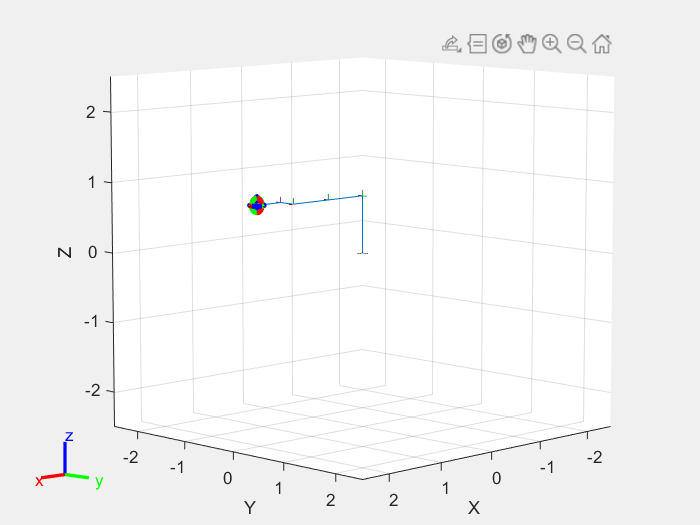

interactiveGUI = interactiveRigidBodyTree(six_rigid, 'Frames', 'on');
interactiveGUI.MarkerScaleFactor = 0.5;

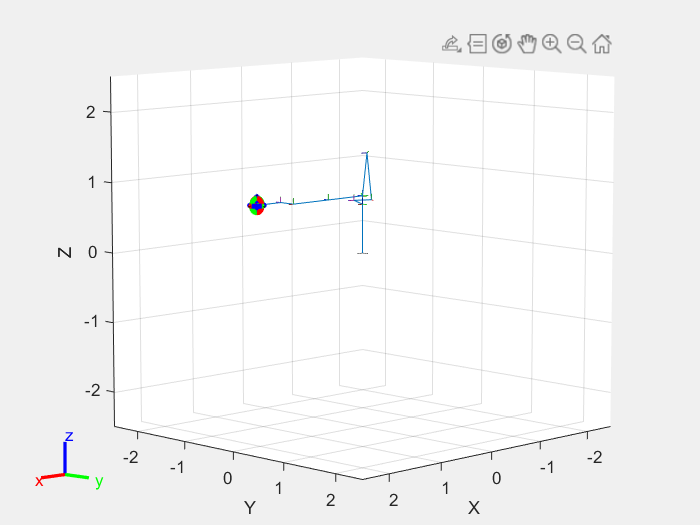

eePosition = [67.5, 67.5, 81.5] * scale;
tform = trvec2tform(eePosition);
ik = inverseKinematics('RigidBodyTree', six_rigid);
weights = [1 0.25 1 0.25 1 1 ];
initialguess = six_rigid.randomConfiguration;
[configSoln,solnInfo] = ik('link5',tform,weights,initialguess);
show(six_rigid,configSoln);

configSolnd = rad2deg(configSoln);
tformsolved = getTransform(six_rigid, configSoln,'link5','base');


%point in sourcebody to the targetbody
%sequence: src, tar

%config = homeConfiguration(six_rigid);
config = randomConfiguration(six_rigid);

T01 = getTransform(six_rigid,config,'link1','base');
T12 = getTransform(six_rigid,config,'link2','link1');
T23 = getTransform(six_rigid,config,'link3','link2');
T34 = getTransform(six_rigid,config,'link4','link3');
T44prime = getTransform(six_rigid,config,'link4prime','link4');
T4prime5 = getTransform(six_rigid,config,'link5','link4prime');
T05 = getTransform(six_rigid,config,'link5','base');


syms th1 th2 th3 th4 th5
%for symbolic representation, alpha_i_neg_one,a_i_neg_one,d_i,theta_i
T01s = TransformMatrix(0, 0, 81.5, th1, false);
T12s = TransformMatrix(pi/2, 0, 0, th2, false);
T23s = TransformMatrix(0, 67.5, 0, th3, false);
T34s = TransformMatrix(0, 67.5, 0, th4, false);
T44primes = TransformMatrix(0, 0, 25.5, 0, false);
T4prime5s = TransformMatrix(-pi/2, 45, 0, th5, false);
T05s = T01s.syms*T12s.syms*T23s.syms*T34s.syms*T44primes.syms*T4prime5s.syms;
simplify(T01s.syms)

$$ans = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{1}\right) & -\sin\left({\mathrm{th}}_{1}\right) & 0 & 0\\ \sin\left({\mathrm{th}}_{1}\right) & \cos\left({\mathrm{th}}_{1}\right) & 0 & 0\\ 0 & 0 & 1 & \frac{163}{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

simplify(T12s.syms)

$$ans = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{2}\right) & -\sin\left({\mathrm{th}}_{2}\right) & 0 & 0\\ 0 & 0 & -1 & 0\\ \sin\left({\mathrm{th}}_{2}\right) & \cos\left({\mathrm{th}}_{2}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

simplify(T23s.syms)

$$ans = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{3}\right) & -\sin\left({\mathrm{th}}_{3}\right) & 0 & \frac{135}{2}\\ \sin\left({\mathrm{th}}_{3}\right) & \cos\left({\mathrm{th}}_{3}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

simplify(T34s.syms)

$$ans = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{4}\right) & -\sin\left({\mathrm{th}}_{4}\right) & 0 & \frac{135}{2}\\ \sin\left({\mathrm{th}}_{4}\right) & \cos\left({\mathrm{th}}_{4}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

simplify(T44primes.syms)

$$ans = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & \frac{51}{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

simplify(T4prime5s.syms)

$$ans = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{5}\right) & -\sin\left({\mathrm{th}}_{5}\right) & 0 & 45\\ 0 & 0 & 1 & 0\\ -\sin\left({\mathrm{th}}_{5}\right) & -\cos\left({\mathrm{th}}_{5}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

simplify(T05s)

T01s_INV = inverse(T01s);
simplify(T01s_INV)

$$ans = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{1}\right) & \sin\left({\mathrm{th}}_{1}\right) & 0 & 0\\ -\sin\left({\mathrm{th}}_{1}\right) & \cos\left({\mathrm{th}}_{1}\right) & 0 & 0\\ 0 & 0 & 1 & -\frac{163}{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T15s = T01s_INV * T05s;
simplify(T15s)

$$ans = \begin{array}{l} \left(\begin{array}{cccc} \frac{\cos\left({\mathrm{th}}_{2}+{\mathrm{th}}_{3}+{\mathrm{th}}_{4}+{\mathrm{th}}_{5}\right)}{2}+\frac{\cos\left({\mathrm{th}}_{2}+{\mathrm{th}}_{3}+{\mathrm{th}}_{4}-{\mathrm{th}}_{5}\right)}{2} & \frac{\sin\left({\mathrm{th}}_{2}+{\mathrm{th}}_{3}+{\mathrm{th}}_{4}-{\mathrm{th}}_{5}\right)}{2}-\frac{\sin\left({\mathrm{th}}_{2}+{\mathrm{th}}_{3}+{\mathrm{th}}_{4}+{\mathrm{th}}_{5}\right)}{2} & -\sigma_{1} & 45\,\sigma_{2}+\frac{135\,\cos\left({\mathrm{th}}_{2}+{\mathrm{th}}_{3}\right)}{2}+\frac{135\,\cos\left({\mathrm{th}}_{2}\right)}{2}\\ \sin\left({\mathrm{th}}_{5}\right) & \cos\left({\mathrm{th}}_{5}\right) & 0 & -\frac{51}{2}\\ \sigma_{1}\,\cos\left({\mathrm{th}}_{5}\right) & -\sigma_{1}\,\sin\left({\mathrm{th}}_{5}\right) & \sigma_{2} & 45\,\sigma_{1}+\frac{135\,\sin\left({\mathrm{th}}_{2}+{\mathrm{th}}_{3}\right)}{2}+\frac{135\,\sin\left({\mathrm{th}}_{2}\right)}{2}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left({\mathrm{th}}_{2}+{\mathrm{th}}_{3}+{\mathrm{th}}_{4}\right)\\ \sigma_{2}=\cos\left({\mathrm{th}}_{2}+{\mathrm{th}}_{3}+{\mathrm{th}}_{4}\right) \end{array}$$

T12s_INV = inverse(T12s);
simplify(T12s_INV)

$$ans = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{2}\right) & 0 & \sin\left({\mathrm{th}}_{2}\right) & 0\\ -\sin\left({\mathrm{th}}_{2}\right) & 0 & \cos\left({\mathrm{th}}_{2}\right) & 0\\ 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T25s = T12s_INV * T15s;
simplify(T25s)

$$ans = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{3}+{\mathrm{th}}_{4}\right)\,\cos\left({\mathrm{th}}_{5}\right) & -\cos\left({\mathrm{th}}_{3}+{\mathrm{th}}_{4}\right)\,\sin\left({\mathrm{th}}_{5}\right) & -\sin\left({\mathrm{th}}_{3}+{\mathrm{th}}_{4}\right) & 45\,\cos\left({\mathrm{th}}_{3}+{\mathrm{th}}_{4}\right)+\frac{135\,\cos\left({\mathrm{th}}_{3}\right)}{2}+\frac{135}{2}\\ \sin\left({\mathrm{th}}_{3}+{\mathrm{th}}_{4}\right)\,\cos\left({\mathrm{th}}_{5}\right) & -\sin\left({\mathrm{th}}_{3}+{\mathrm{th}}_{4}\right)\,\sin\left({\mathrm{th}}_{5}\right) & \cos\left({\mathrm{th}}_{3}+{\mathrm{th}}_{4}\right) & 45\,\sin\left({\mathrm{th}}_{3}+{\mathrm{th}}_{4}\right)+\frac{135\,\sin\left({\mathrm{th}}_{3}\right)}{2}\\ -\sin\left({\mathrm{th}}_{5}\right) & -\cos\left({\mathrm{th}}_{5}\right) & 0 & \frac{51}{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$